clearvars
close all
clc

tt = readtable('input_data\08_00-10_00-non-duplicated.csv');

tt.Var1 = [];
tt.Unnamed_0 =[];
tt.arac_id = categorical(tt.arac_id); %make vehicle ids categorical data type to efficiency
tt.tarih = [];
tt.UNIX_TIMESTAMP = [];
tt.Properties.VariableNames{4} = 'time';
tt=sortrows(tt,{'arac_id','time'});

tt.time_num=zeros(size(tt,1),1); %create cloumn
func_numerator = @(x) {transpose(1:1:length(x))}; 

[G] = findgroups(tt.arac_id); %category indexes
tt.time_num = uint64(cell2mat(splitapply(func_numerator,G,G))); %table must be ordered to assign time_numerator correctly

n_duplicates = size(tt(:,2:end),1) - size(unique(tt(:,{'arac_id','time'})),1)

n_duplicates = 0

osrm_data_sp = load('output_data_v2\osrm_output_with_speed.mat').out;
aug_data = load('output_data_v2\aug_output.mat').aug_data;
segments = load('input_data\osm.mat').osm;
markers = load('input_data\markers.mat').markers;
% adding distance from origin column to aug_out
[~,b] = ismember(aug_data.segment_id,segments.segment_id);
aug_data.distance_from_start = segments.distance_from_start(b);

corridor_length = 1e-3 * max(sum(segments(segments.dir==2,:).calc_length) , sum(segments(segments.dir==1,:).calc_length));
osrm_data_sp.Properties.VariableNames{10} = 'dir';
osrm_data_sp.Properties.VariableNames{11} = 'segment_id';
aug_data.Properties.VariableNames{2} = 'time';
osrm_data_sp.Properties.VariableNames{4} = 'time';

aux_segments = unique(aug_data.segment_id);
filter = NaN(size(aug_data,1),1);
for i=1:1:length(aux_segments)
    filter(aug_data.segment_id == aux_segments(i)) = isoutlier(aug_data(aug_data.segment_id == aux_segments(i),:).speed,'quartiles');
end
aug_data.filter = ~logical(filter);
size(aug_data,1)

ans = 114587

sum(filter)

ans = 2669


aux_segments = unique(osrm_data_sp.segment_id);
filter = NaN(size(osrm_data_sp,1),1);
for i=1:1:length(aux_segments)
    filter(osrm_data_sp.segment_id == aux_segments(i)) = isoutlier(osrm_data_sp(osrm_data_sp.segment_id == aux_segments(i),:).speed,'quartiles');
end
osrm_data_sp.filter = ~logical(filter);
size(osrm_data_sp,1)

ans = 114833

sum(filter)

ans = 3666

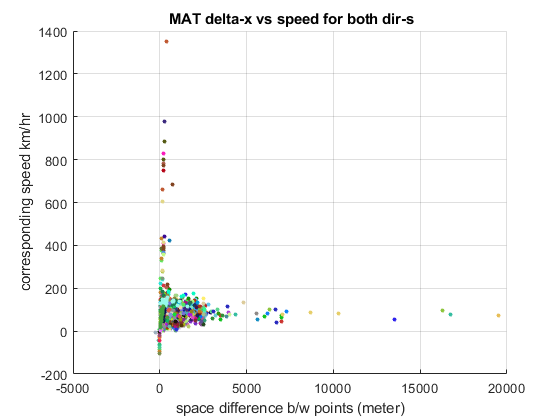

[a,b] = findgroups(osrm_data_sp.arac_id);
color_1 =  rand(length(b),3);

scatter(osrm_data_sp.space_distance,osrm_data_sp.speed,10,color_1(a,:),'filled')
xlabel('space difference b/w points (meter)')
ylabel('corresponding speed km/hr')
grid on
title(' MAT delta-x vs speed for both dir-s')

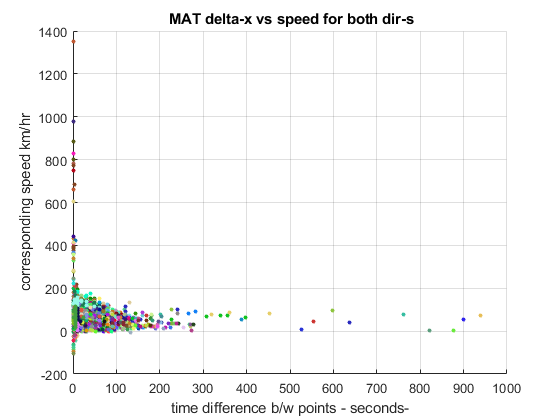

scatter(osrm_data_sp.time_distance * 60 * 60,osrm_data_sp.speed,10,color_1(a,:),'filled')
xlabel('time difference b/w points - seconds-')
ylabel('corresponding speed km/hr')
grid on
title(' MAT delta-x vs speed for both dir-s')

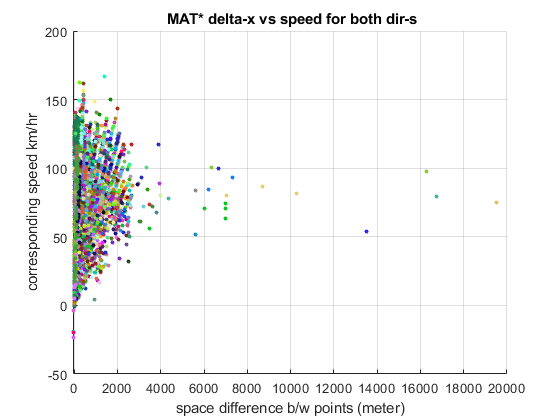


scatter(osrm_data_sp(osrm_data_sp.filter,:).space_distance,osrm_data_sp(osrm_data_sp.filter,:).speed,10,color_1(a(osrm_data_sp.filter),:),'filled')
xlabel('space difference b/w points (meter)')
ylabel('corresponding speed km/hr')
grid on
title(' MAT* delta-x vs speed for both dir-s')

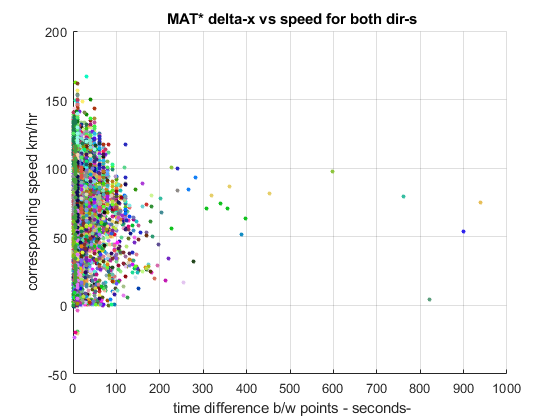


scatter(osrm_data_sp(osrm_data_sp.filter,:).time_distance * 60 * 60,osrm_data_sp(osrm_data_sp.filter,:).speed,10,color_1(a(osrm_data_sp.filter),:),'filled')
xlabel(' time difference b/w points - seconds-')
ylabel('corresponding speed km/hr')
grid on
title(' MAT* delta-x vs speed for both dir-s')

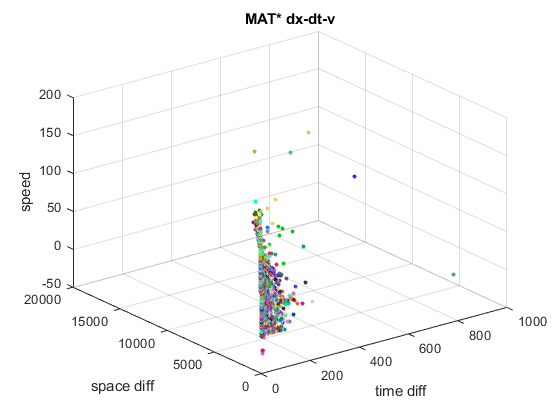


scatter3(osrm_data_sp(osrm_data_sp.filter,:).time_distance * 60 * 60,osrm_data_sp(osrm_data_sp.filter,:).space_distance,osrm_data_sp(osrm_data_sp.filter,:).speed,10,color_1(a(osrm_data_sp.filter),:),'filled')
xlabel('time diff')
ylabel('space diff')
zlabel('speed')
grid on
title('MAT* dx-dt-v')


% 500 'den fazla olan datalar

thres = 200;

index = osrm_data_sp.speed > thres;
get_data = unique(osrm_data_sp(index,{'arac_id','route_id'}));

% bu dataları barındıran rotalar
% a = unique(get_data(:,));

selected_data = table;

for i = 1:1:size(get_data,1)
    index1 = osrm_data_sp.arac_id == get_data.arac_id(i);
    index2 = osrm_data_sp.route_id == get_data.route_id(i);
    index3 = logical(index1 .* index2);
    
    selected_data = vertcat(selected_data,osrm_data_sp(index3,:));
%     [b, c] = ismember(a,osrm_data_sp(:,{'arac_id','route_id'}),'rows');
end

unique(selected_data.arac_id)

ans = 23×1 categorical array
     3bx0r4x 
     cttnol3 
     l50l3qc 
     nzktcol 
     ppwpzyx 
     pvy33tw 
     sns16bb 
     tjzpnzu 
     tkczccw 
     v8i2v2v 
     wv3utz3 
     x94o15q 
     xuunlr0 
     ykkuu0x 
     ykv00ty 
     yvv3wty 
     27jjpjpk 
     ktwuoqq 
     ujvupvc 
     wzywc03 
     l6xs3c0l 
     tpkywzw 
     obno0qs 


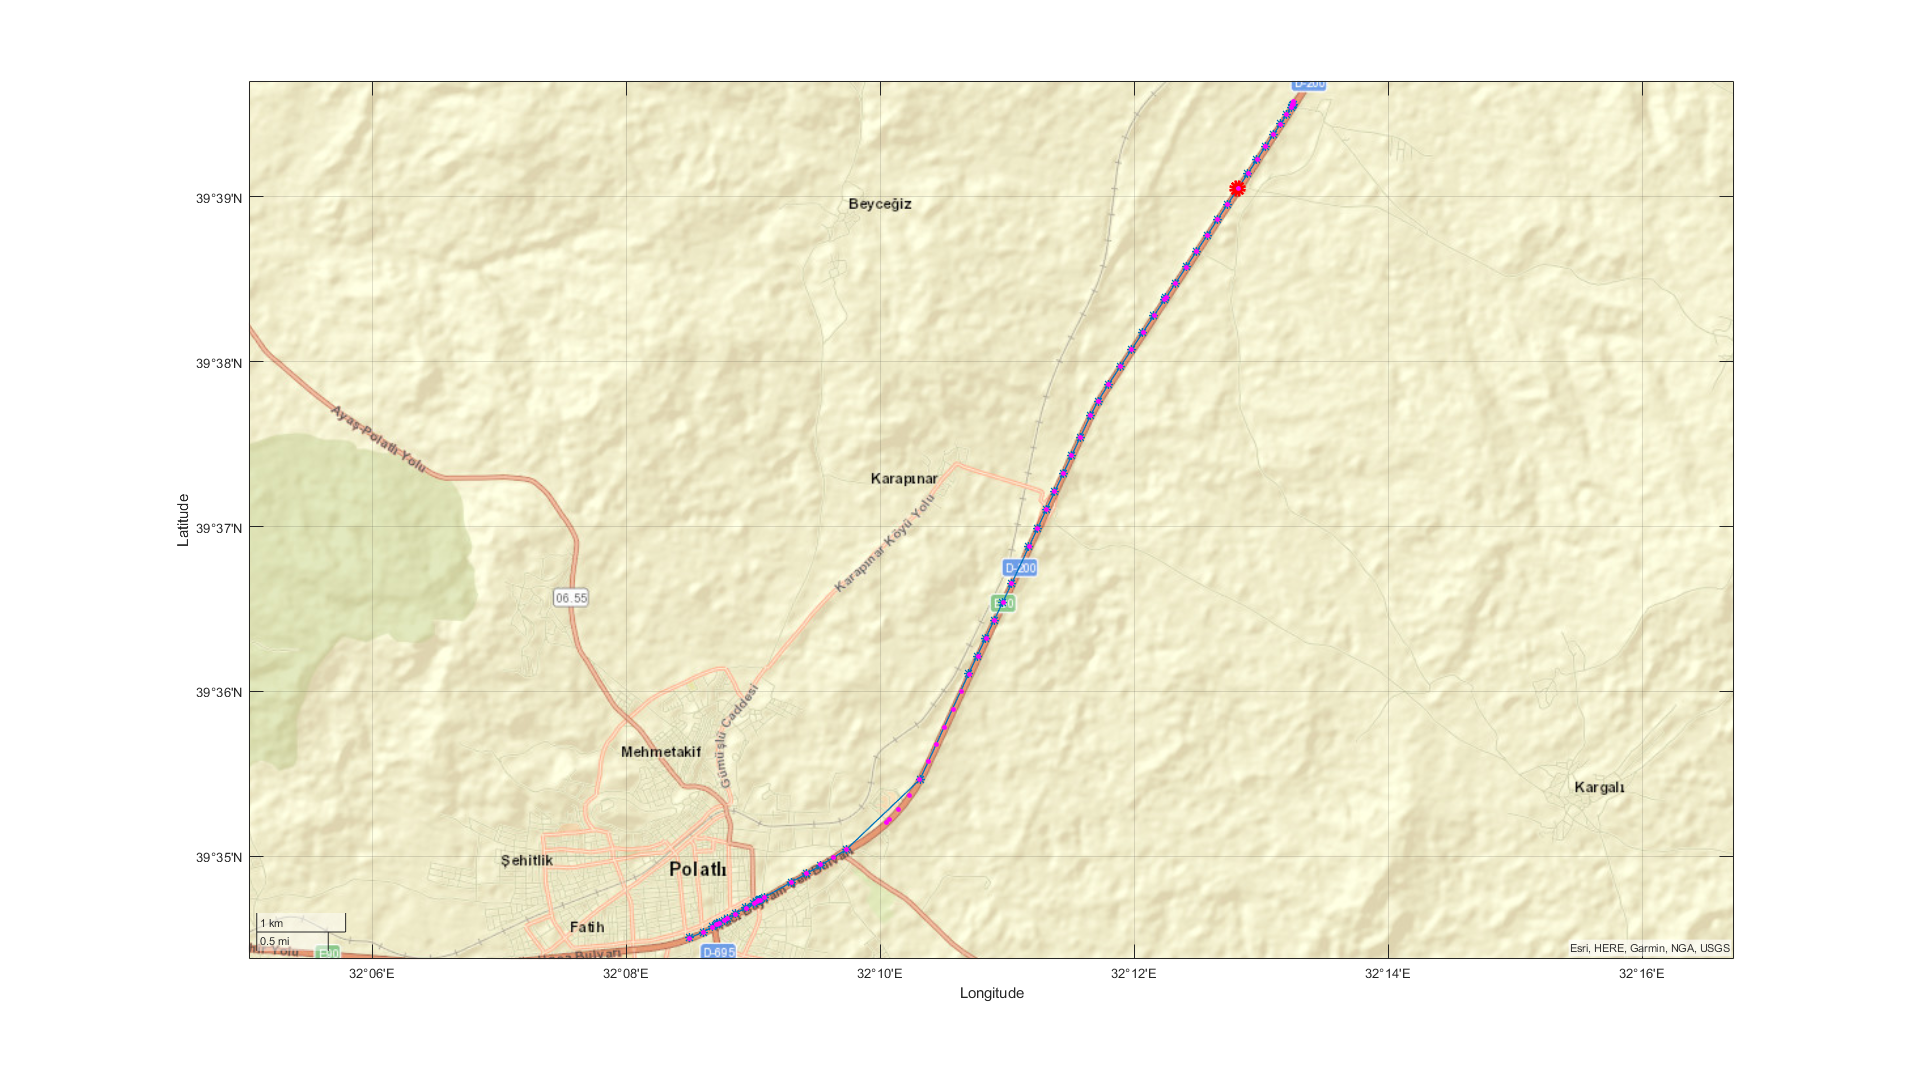

% q9oc158
% 3bx0r4x 
%      caqc481 

%      cttnol3 

%      3bx0r4x 



selected_arac_id = '3bx0r4x';
selected_data(~(selected_data.arac_id == selected_arac_id),:) = [];

a = findgroups(selected_data(:,{'arac_id','route_id'}));

h = figure();

for i=1:1:max(a)
    aux_index = a == i;
    
    s1 = geoplot(selected_data.lat(aux_index),selected_data.lon(aux_index),"Marker","*","LineWidth",1);
    hold on
    s1.DataTipTemplate.DataTipRows(3)=dataTipTextRow('arac-id',cellstr(selected_data.arac_id(aux_index)));
    s1.DataTipTemplate.DataTipRows(4)=dataTipTextRow('time',cellstr(selected_data.time(aux_index)));
    s1.DataTipTemplate.DataTipRows(1:2)=[];
    
    s2 = geoscatter(selected_data.lat(logical(aux_index .* (selected_data.speed> thres))), selected_data.lon(logical(aux_index .* (selected_data.speed> thres))),60,'red',"LineWidth",5);
    s2.DataTipTemplate.DataTipRows(3)=dataTipTextRow('arac-id',cellstr(selected_data.arac_id(logical(aux_index .* (selected_data.speed> thres)))));
    s2.DataTipTemplate.DataTipRows(4)=dataTipTextRow('time',cellstr(selected_data.time(logical(aux_index .* (selected_data.speed> thres)))));
    s2.DataTipTemplate.DataTipRows(1:2)=[];
    
    
%     s2.DataTipTemplate.DataTipRows(3) = 
    
    
    
    
    % hold on
    % s2=geoscatter(T_aug.lat(loc_aug),T_aug.lon(loc_aug),120,'black');
    % s2.DataTipTemplate.DataTipRows(3)=dataTipTextRow('Time',cellstr(datestr(T_aug.time(loc_aug))));
    % hold on
    % s3=geoscatter(osm.startLat(osm.dir==1),osm.startLon(osm.dir==1),90,'s','blue'); %start
    % hold on
    % s4=geoscatter(osm.endLat(osm.dir==1),osm.endLon(osm.dir==1),15,'s','blue','filled'); %end
    % hold on
    % s5=geoscatter(osm.startLat(osm.dir==2),osm.startLon(osm.dir==2),90,'s','blue'); %start
    % hold on
    % s6=geoscatter(osm.endLat(osm.dir==2),osm.endLon(osm.dir==2),15,'s','blue','filled'); %end
    
    % legend('real','aug','segments start','segments end')
    % title(['arac id ', T_arac.arac_cats{fig_arac_id}]);
    % 
    % 
    % text(T_real.lat(loc_real),T_real.lon(loc_real),num2str(T_real.time_num(loc_real)))
    hold on
end


s3 = geoscatter(tt.latitude(tt.arac_id == selected_arac_id), tt.longitude(tt.arac_id == selected_arac_id),15,'filled','magenta',"LineWidth",0.1);
s3.DataTipTemplate.DataTipRows(3)=dataTipTextRow('arac-id',cellstr(tt.arac_id(tt.arac_id == selected_arac_id)));
s3.DataTipTemplate.DataTipRows(4)=dataTipTextRow('time',cellstr(tt.time(tt.arac_id == selected_arac_id)));
s3.DataTipTemplate.DataTipRows(1:2)=[];


% alpha(s3,0.65);

geobasemap streets
set(h,'Units','normalized','Position',[0 0 1 1]);

% aux_index .* (selected_data.speed> thres);
raw_data = tt(tt.arac_id == selected_arac_id,:);
matchs = selected_data(aux_index,:);
matchs.dV = [NaN; diff(matchs.speed)] * 1000 / 3600;
matchs.acc = (matchs.dV ./ (matchs.time_distance* 3600)) ;

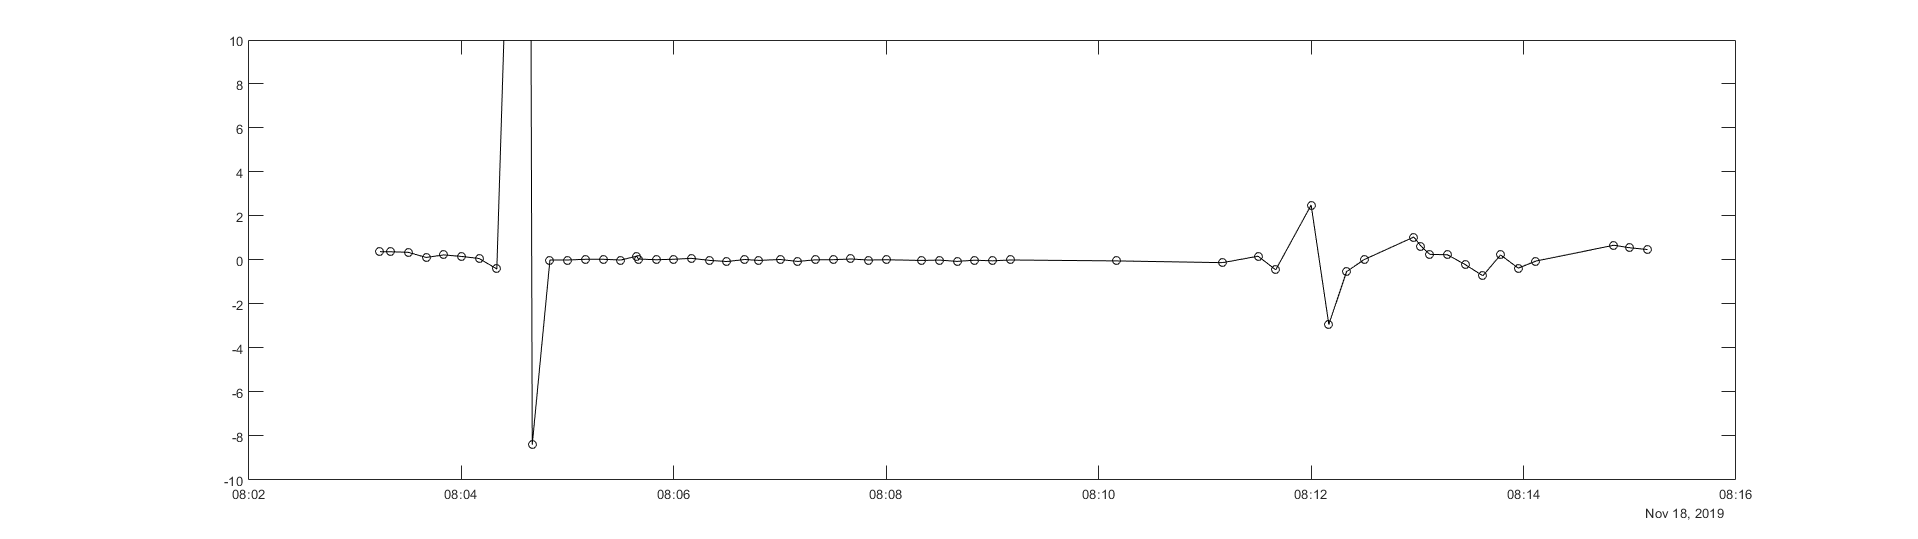

h = figure();

plot(matchs.time, matchs.acc,'-ok'); 
hold on
% plot(matchs.time, matchs.speed,'-*'); 
set(h,'Units','normalized','Position',[0 0 1 0.5]);
ylim([-10 10])

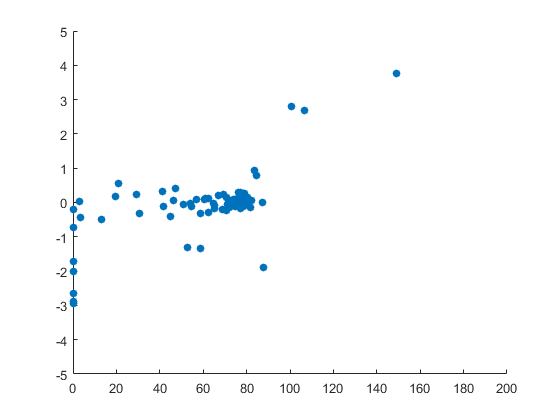

h = figure();
scatter(matchs.speed,matchs.acc,'filled');
ylim([-5 5])
xlim([0 200])

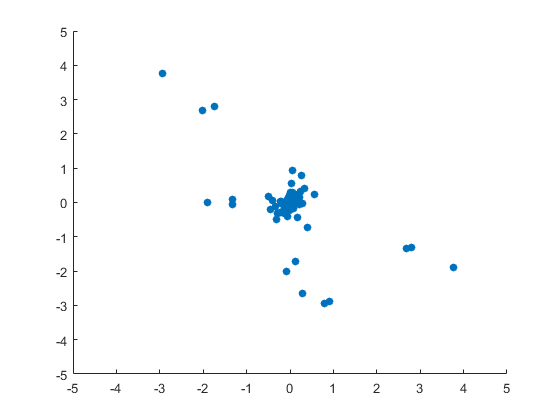

h = figure();
scatter(matchs.acc(1:end-1),matchs.acc(2:end),'filled');
ylim([-5 5])
xlim([-5 5])

% xlim([0 200])